** 1 Obiekt inercyjny I rzędu**

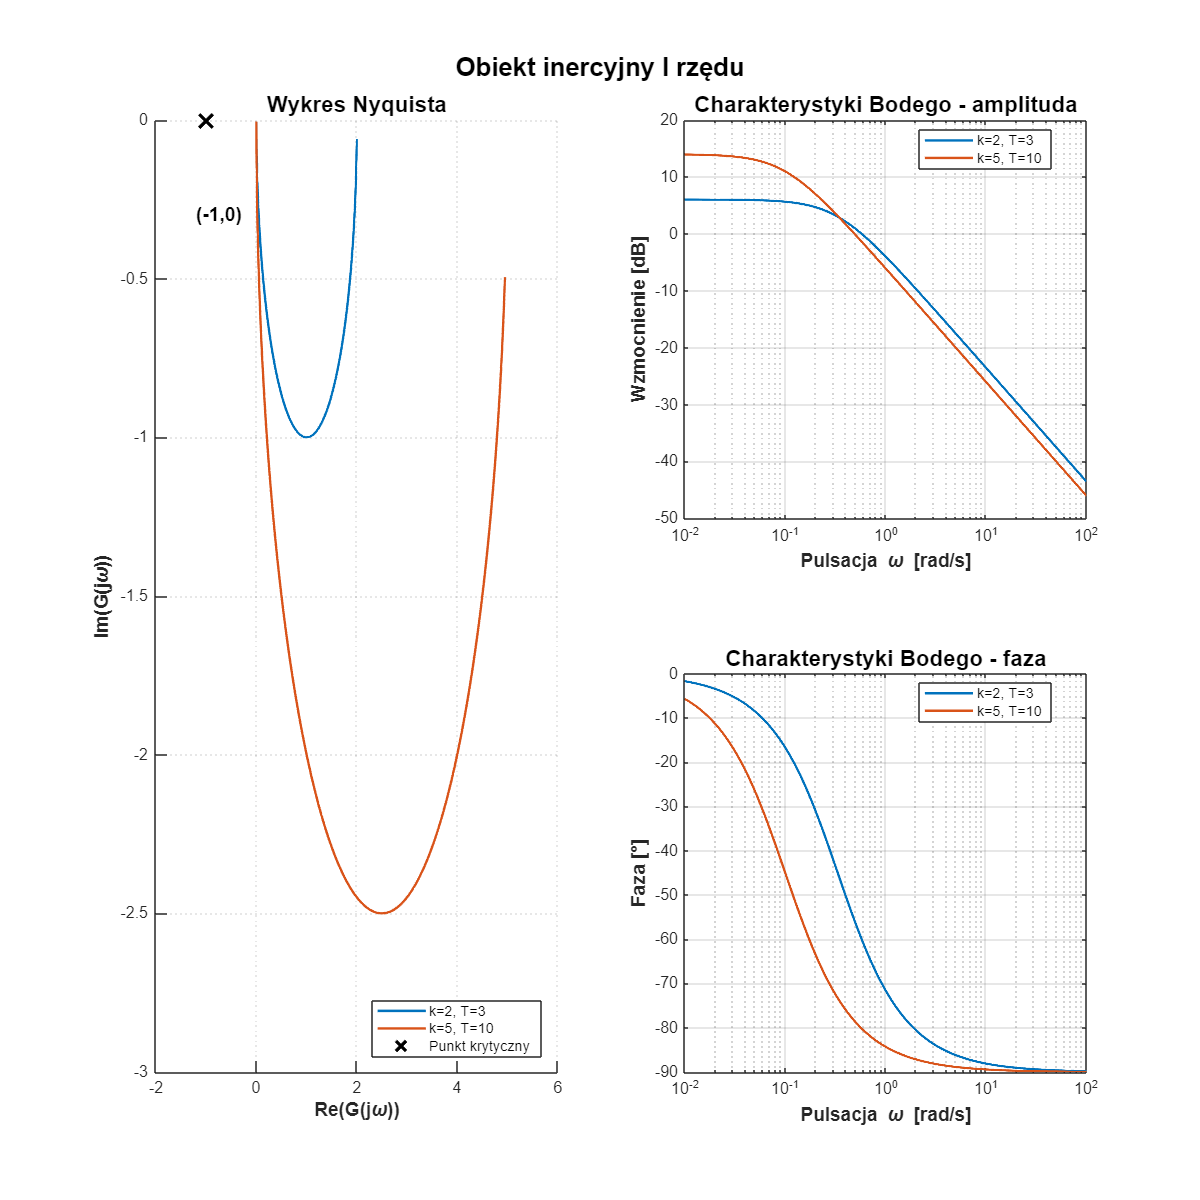

clear; close all; clc;

% Parametry układów
k = [2, 5];
T = [3, 10];

% Zakres pulsacji
w = logspace(-2, 2, 2000);
s = 1j * w;

% Obliczanie odpowiedzi częstotliwościowej
G = cell(1,2);
mag = cell(1,2);
phase = cell(1,2);

for i = 1:2
    G{i} = k(i) ./ (T(i)*s + 1);
    mag{i} = abs(G{i});
    phase{i} = angle(G{i}) * 180/pi;
end

% Kolory dla wykresów
colors = lines(2);

% Tworzenie okna wykresów
figure('Position', [100, 100, 1000, 1000]);
sgtitle('Obiekt inercyjny I rzędu', 'FontSize', 16, 'FontWeight', 'bold');

%% Wykres Nyquista (lewa strona)
subplot(1,2,1);
hold on;
for i = 1:2
    plot(real(G{i}), imag(G{i}), 'Color', colors(i,:), 'LineWidth', 1.5);
end
plot(-1, 0, 'kx', 'MarkerSize', 12, 'LineWidth', 2);
text(-1.2, -0.3, '(-1,0)', 'FontSize', 12, 'FontWeight', 'bold');
set(gca, 'GridLineStyle', ':');
hold off;
grid on;
axis([-2 6 -3 0]);
title('Wykres Nyquista', 'FontWeight', 'bold', 'FontSize', 14);
xlabel('Re(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Im(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
legend({sprintf('k=%d, T=%d', k(1), T(1)), ...
        sprintf('k=%d, T=%d', k(2), T(2)), ...
        'Punkt krytyczny'}, 'Location', 'best');

%% Wykresy Bodego (prawa strona)
% Amplituda
subplot(2,2,2);
semilogx(w, 20*log10(mag{1}), 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, 20*log10(mag{2}), 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Wzmocnienie [dB]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - amplituda', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('k=%d, T=%d', k(1), T(1)), ...
        sprintf('k=%d, T=%d', k(2), T(2))}, 'Location', 'best');

% Faza
subplot(2,2,4);
semilogx(w, phase{1}, 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, phase{2}, 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Faza [°]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - faza', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('k=%d, T=%d', k(1), T(1)), ...
        sprintf('k=%d, T=%d', k(2), T(2))}, 'Location', 'best');

set(findall(gcf, '-property', 'FontName'), 'FontName', 'Arial');

**2 Obiekt inercyjny II rzędu**

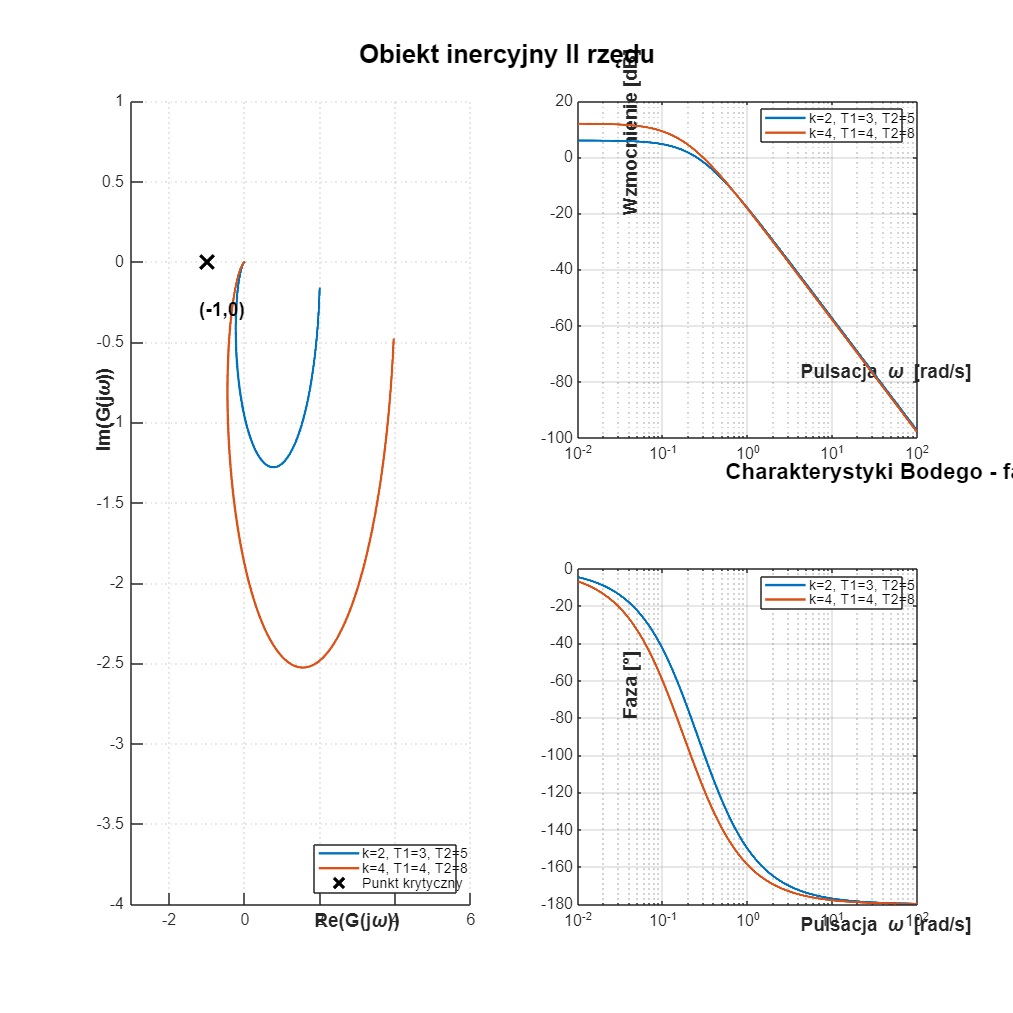

k  = [2, 4];
T1 = [3, 4];
T2 = [5, 8];

w = logspace(-2, 2, 2000);
s = 1j * w;

G     = cell(1,2);
mag   = cell(1,2);
phase = cell(1,2);

for i = 1:2
    G{i} = k(i) ./ (T1(i)*T2(i)*s.^2 + (T1(i)+T2(i))*s + 1);
    mag{i} = abs(G{i});
    phase{i} = angle(G{i}) * 180/pi;
end

figure('Position', [100, 100, 1000, 1000]);
sgtitle('Obiekt inercyjny II rzędu', 'FontSize', 16, 'FontWeight', 'bold');

colors = lines(2);

%% Wykres Nyquista (lewa strona)
subplot(1,2,1);
hold on;
for i = 1:2
    plot(real(G{i}), imag(G{i}), 'Color', colors(i,:), 'LineWidth', 1.5);
end
plot(-1, 0, 'kx', 'MarkerSize', 12, 'LineWidth', 2);
text(-1.2, -0.3, '(-1,0)', 'FontSize', 12, 'FontWeight', 'bold');
set(gca, 'GridLineStyle', ':');
hold off;
grid on;
axis([-3 6 -4 1]);
title('Wykres Nyquista', 'FontWeight', 'bold', 'FontSize', 14);
xlabel('Re(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Im(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
legend({sprintf('k=%d, T1=%d, T2=%d', k(1), T1(1), T2(1)), ...
        sprintf('k=%d, T1=%d, T2=%d', k(2), T1(2), T2(2)), ...
        'Punkt krytyczny'}, 'Location', 'best');

%% Wykresy Bodego (prawa strona)
% Amplituda
subplot(2,2,2);
semilogx(w, 20*log10(mag{1}), 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, 20*log10(mag{2}), 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Wzmocnienie [dB]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - amplituda', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('k=%d, T1=%d, T2=%d', k(1), T1(1), T2(1)), ...
        sprintf('k=%d, T1=%d, T2=%d', k(2), T1(2), T2(2))}, 'Location', 'best');

% Faza
subplot(2,2,4);
semilogx(w, phase{1}, 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, phase{2}, 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Faza [°]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - faza', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('k=%d, T1=%d, T2=%d', k(1), T1(1), T2(1)), ...
        sprintf('k=%d, T1=%d, T2=%d', k(2), T1(2), T2(2))}, 'Location', 'best');

set(findall(gcf, '-property', 'FontName'), 'FontName', 'Arial');

**3 Obiekt oscylacyjny II rzędu**

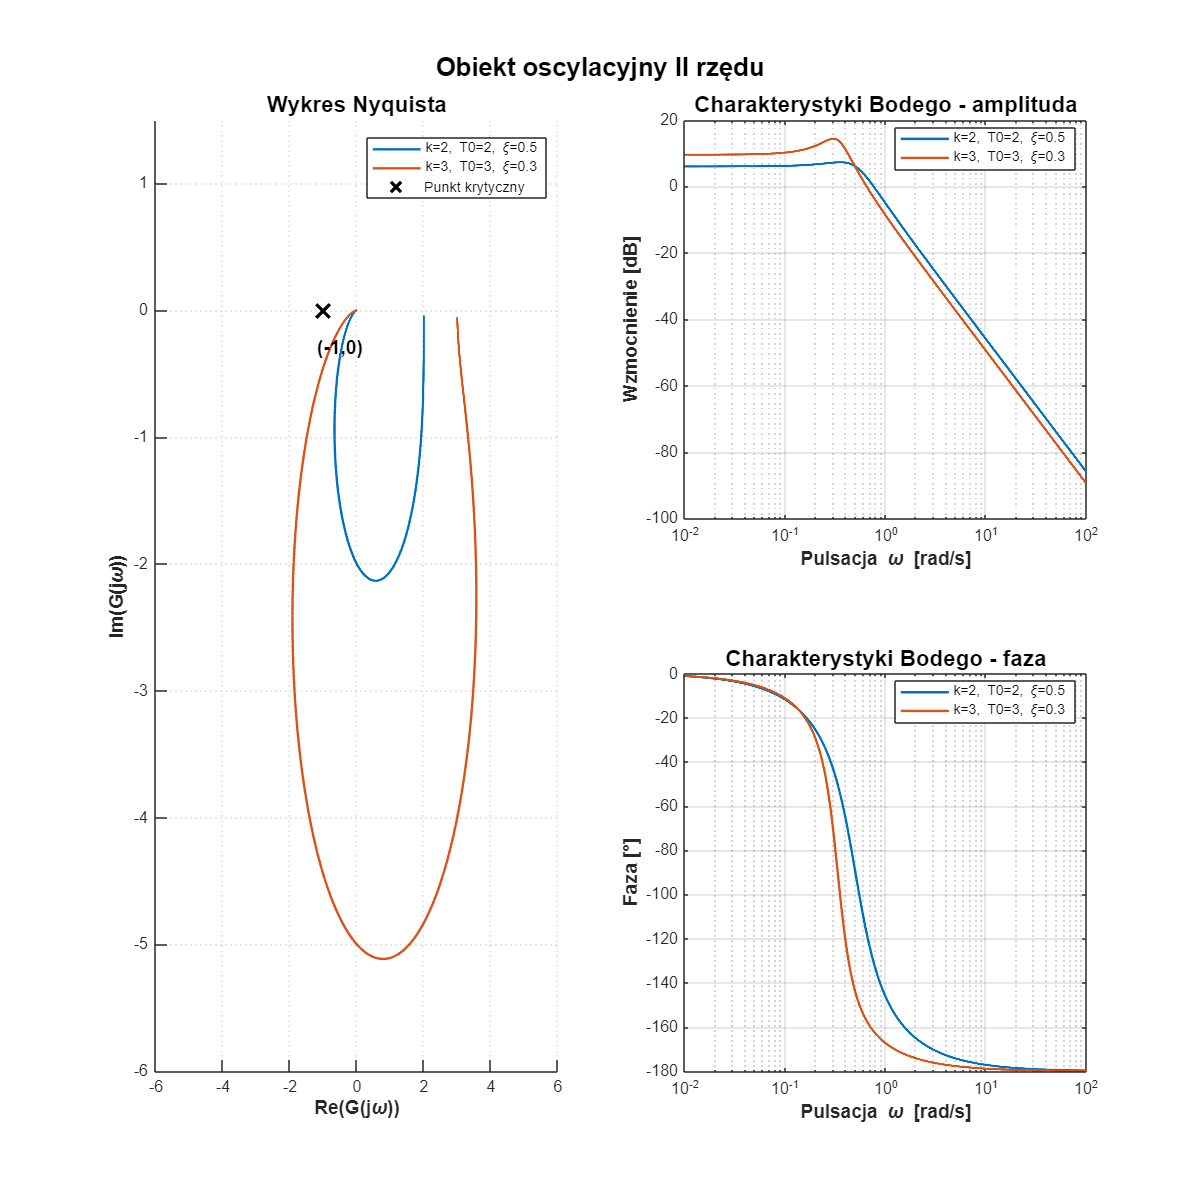

k  = [2, 3];
T0 = [2, 3];
xi = [0.5, 0.3];

w = logspace(-2, 2, 2000);
s = 1j * w;

G     = cell(1,2);
mag   = cell(1,2);
phase = cell(1,2);

for i = 1:2
    G{i} = k(i) ./ (T0(i)^2 * s.^2 + 2*xi(i)*T0(i)*s + 1);
    mag{i} = abs(G{i});
    phase{i} = angle(G{i}) * 180/pi;
end

figure('Position', [100, 100, 1000, 1000]);
sgtitle('Obiekt oscylacyjny II rzędu', 'FontSize', 16, 'FontWeight', 'bold');

colors = lines(2);

%% Wykres Nyquista (lewa strona)
subplot(1,2,1);
hold on;
for i = 1:2
    plot(real(G{i}), imag(G{i}), 'Color', colors(i,:), 'LineWidth', 1.5);
end
plot(-1, 0, 'kx', 'MarkerSize', 12, 'LineWidth', 2);
text(-1.2, -0.3, '(-1,0)', 'FontSize', 12, 'FontWeight', 'bold');
set(gca, 'GridLineStyle', ':');
hold off;
grid on;
axis([-6 6 -6 1.5]);
title('Wykres Nyquista', 'FontWeight', 'bold', 'FontSize', 14);
xlabel('Re(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Im(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
legend({sprintf('k=%d, T0=%d, \\xi=%.1f', k(1), T0(1), xi(1)), ...
        sprintf('k=%d, T0=%d, \\xi=%.1f', k(2), T0(2), xi(2)), ...
        'Punkt krytyczny'}, 'Location', 'best');

%% Wykresy Bodego (prawa strona)
% Amplituda
subplot(2,2,2);
semilogx(w, 20*log10(mag{1}), 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, 20*log10(mag{2}), 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Wzmocnienie [dB]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - amplituda', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('k=%d, T0=%d, \\xi=%.1f', k(1), T0(1), xi(1)), ...
        sprintf('k=%d, T0=%d, \\xi=%.1f', k(2), T0(2), xi(2))}, 'Location', 'best');

% Faza
subplot(2,2,4);
semilogx(w, phase{1}, 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, phase{2}, 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Faza [°]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - faza', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('k=%d, T0=%d, \\xi=%.1f', k(1), T0(1), xi(1)), ...
        sprintf('k=%d, T0=%d, \\xi=%.1f', k(2), T0(2), xi(2))}, 'Location', 'best');

set(findall(gcf, '-property', 'FontName'), 'FontName', 'Arial');

**4 Obiekt całkujący z inercją I rzędu **

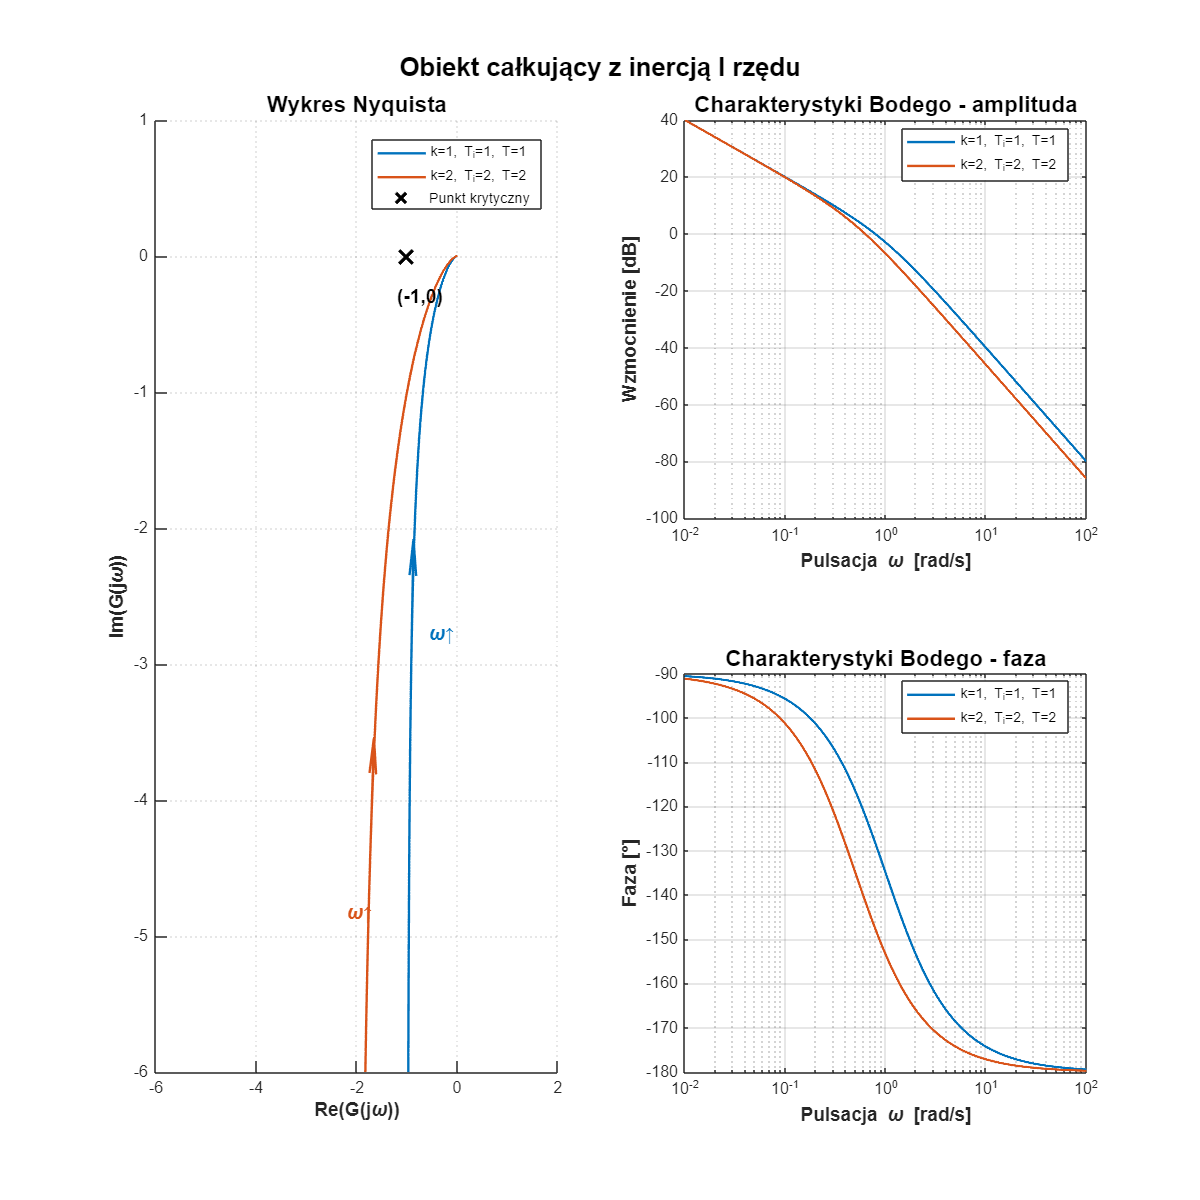

% Parametry układów
k = [1, 2];
T_i = [1, 2];
T = [1, 2];

% Zakres pulsacji
w = logspace(-2, 2, 2000);
s = 1j * w;

% Obliczanie odpowiedzi częstotliwościowej
G = cell(1,2);
mag = cell(1,2);
phase = cell(1,2);

for i = 1:2
    G{i} = k(i) ./ (T_i(i) * s .* (T(i) * s + 1));
    mag{i} = abs(G{i});
    phase{i} = angle(G{i}) * 180/pi;
end

% Tworzenie okna wykresów
figure('Position', [100, 100, 1000, 1000]);
sgtitle('Obiekt całkujący z inercją I rzędu', 'FontSize', 16, 'FontWeight', 'bold');

colors = lines(2);

%% Wykres Nyquista (lewa strona)
subplot(1,2,1);
hold on;
for i = 1:2
    plot(real(G{i}), imag(G{i}), 'Color', colors(i,:), 'LineWidth', 1.5);
end
plot(-1, 0, 'kx', 'MarkerSize', 12, 'LineWidth', 2);
text(-1.2, -0.3, '(-1,0)', 'FontSize', 12, 'FontWeight', 'bold');

% Dodanie strzałek kierunku
arrow_index1 = 750;
arrow_index2 = 650;

idx = arrow_index1;
dx = real(G{1}(idx+10)) - real(G{1}(idx-10));
dy = imag(G{1}(idx+10)) - imag(G{1}(idx-10));
len = sqrt(dx^2 + dy^2);
if len > 0
    dx = dx/len * 0.8;
    dy = dy/len * 0.8;
    quiver(real(G{1}(idx)), imag(G{1}(idx)), dx, dy, 0, 'Color', colors(1,:), 'LineWidth', 1.5, 'MaxHeadSize', 3);
    text(real(G{1}(idx))+0.3, imag(G{1}(idx))+0.1, '\omega↑', 'Color', colors(1,:), 'FontSize', 12, 'FontWeight', 'bold');
end

idx = arrow_index2;
dx = real(G{2}(idx+10)) - real(G{2}(idx-10));
dy = imag(G{2}(idx+10)) - imag(G{2}(idx-10));
len = sqrt(dx^2 + dy^2);
if len > 0
    dx = dx/len * 0.8;
    dy = dy/len * 0.8;
    quiver(real(G{2}(idx)), imag(G{2}(idx)), dx, dy, 0, 'Color', colors(2,:), 'LineWidth', 1.5, 'MaxHeadSize', 3);
    text(real(G{2}(idx))-0.5, imag(G{2}(idx))-0.5, '\omega↑', 'Color', colors(2,:), 'FontSize', 12, 'FontWeight', 'bold');
end

set(gca, 'GridLineStyle', ':');
hold off;
grid on;
axis([-6 2 -6 1]);
title('Wykres Nyquista', 'FontWeight', 'bold', 'FontSize', 14);
xlabel('Re(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Im(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
legend({sprintf('k=%d, T_i=%d, T=%d', k(1), T_i(1), T(1)), ...
        sprintf('k=%d, T_i=%d, T=%d', k(2), T_i(2), T(2)), ...
        'Punkt krytyczny'}, 'Location', 'best');

%% Wykresy Bodego (prawa strona)
% Amplituda
subplot(2,2,2);
semilogx(w, 20*log10(mag{1}), 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, 20*log10(mag{2}), 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Wzmocnienie [dB]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - amplituda', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('k=%d, T_i=%d, T=%d', k(1), T_i(1), T(1)), ...
        sprintf('k=%d, T_i=%d, T=%d', k(2), T_i(2), T(2))}, 'Location', 'best');

% Faza
subplot(2,2,4);
semilogx(w, phase{1}, 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, phase{2}, 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Faza [°]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - faza', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('k=%d, T_i=%d, T=%d', k(1), T_i(1), T(1)), ...
        sprintf('k=%d, T_i=%d, T=%d', k(2), T_i(2), T(2))}, 'Location', 'best');

set(findall(gcf, '-property', 'FontName'), 'FontName', 'Arial');

**5 Obiekt różniczkujący rzeczywisty**

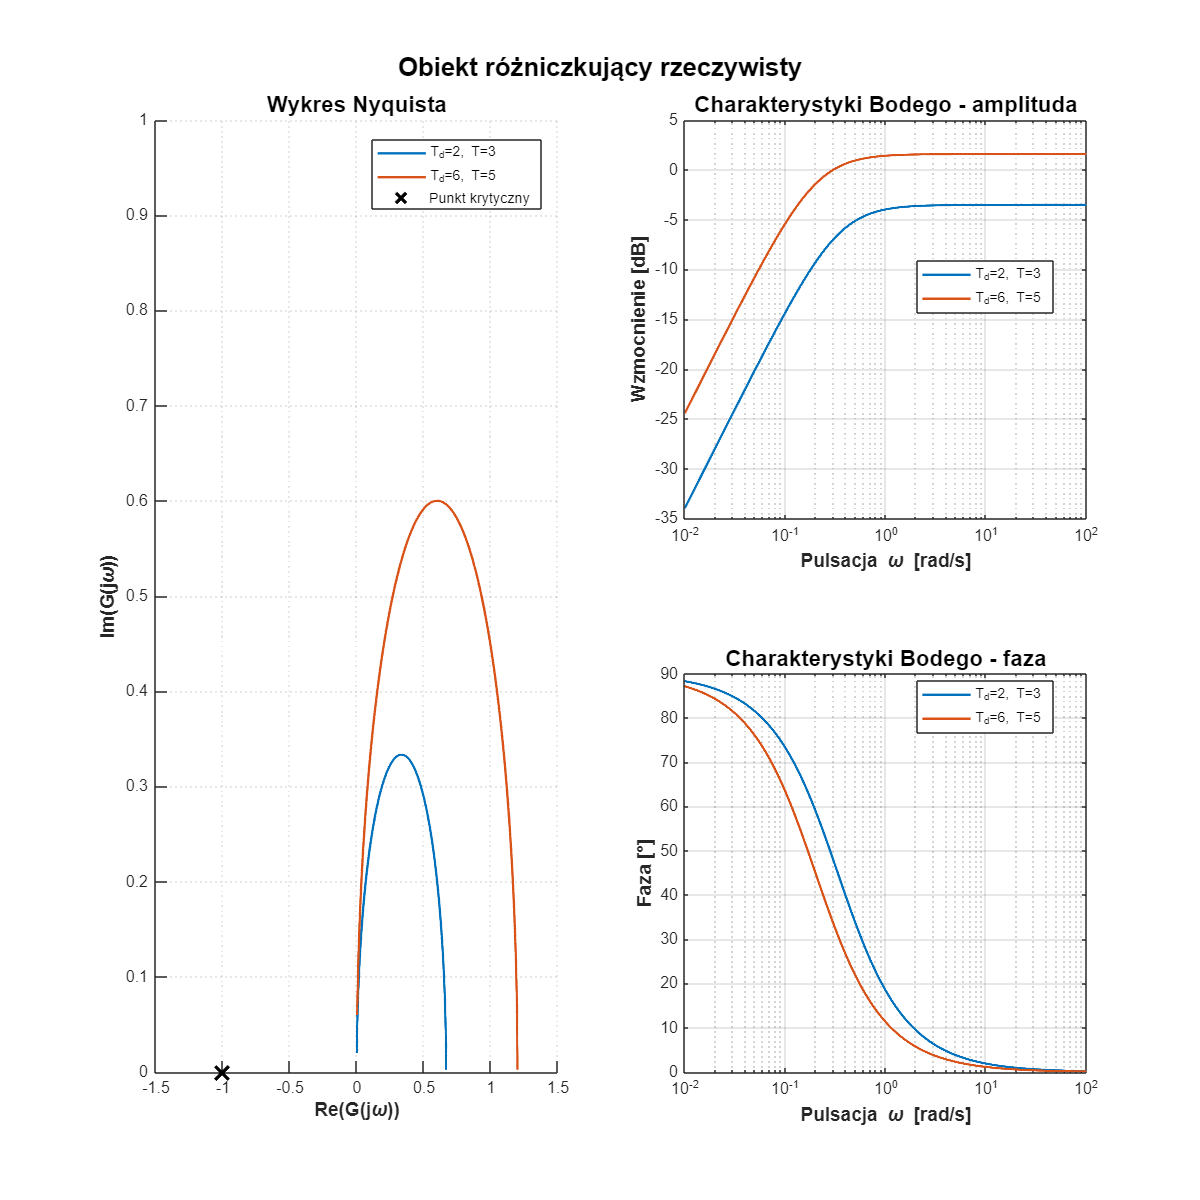

% Parametry układów
Td = [2, 6];
T  = [3, 5];

% Zakres pulsacji
w = logspace(-2, 2, 2000);
s = 1j * w;

% Obliczanie odpowiedzi częstotliwościowej
G     = cell(1,2);
mag   = cell(1,2);
phase = cell(1,2);

for i = 1:2
    G{i} = Td(i) .* s ./ (T(i)*s + 1);
    mag{i} = abs(G{i});
    phase{i} = angle(G{i}) * 180/pi;
end

% Tworzenie okna wykresów
figure('Position', [100, 100, 1000, 1000]);
sgtitle('Obiekt różniczkujący rzeczywisty', 'FontSize', 16, 'FontWeight', 'bold');

colors = lines(2);

%% Wykres Nyquista (lewa strona)
subplot(1,2,1);
hold on;
for i = 1:2
    plot(real(G{i}), imag(G{i}), 'Color', colors(i,:), 'LineWidth', 1.5);
end
plot(-1, 0, 'kx', 'MarkerSize', 12, 'LineWidth', 2);
text(-1.2, -0.3, '(-1,0)', 'FontSize', 12, 'FontWeight', 'bold');
set(gca, 'GridLineStyle', ':');
hold off;
grid on;
axis([-1.5 1.5 0 1]);
title('Wykres Nyquista', 'FontWeight', 'bold', 'FontSize', 14);
xlabel('Re(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Im(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
legend({sprintf('T_d=%d, T=%d', Td(1), T(1)), ...
        sprintf('T_d=%d, T=%d', Td(2), T(2)), ...
        'Punkt krytyczny'}, 'Location', 'best');

%% Wykresy Bodego (prawa strona)
% Amplituda
subplot(2,2,2);
semilogx(w, 20*log10(mag{1}), 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, 20*log10(mag{2}), 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Wzmocnienie [dB]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - amplituda', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('T_d=%d, T=%d', Td(1), T(1)), ...
        sprintf('T_d=%d, T=%d', Td(2), T(2))}, 'Location', 'best');

% Faza
subplot(2,2,4);
semilogx(w, phase{1}, 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, phase{2}, 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Faza [°]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - faza', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('T_d=%d, T=%d', Td(1), T(1)), ...
        sprintf('T_d=%d, T=%d', Td(2), T(2))}, 'Location', 'best');

set(findall(gcf, '-property', 'FontName'), 'FontName', 'Arial');

**6 Obiekt inercyjny I rzędu z opóźnieniem**

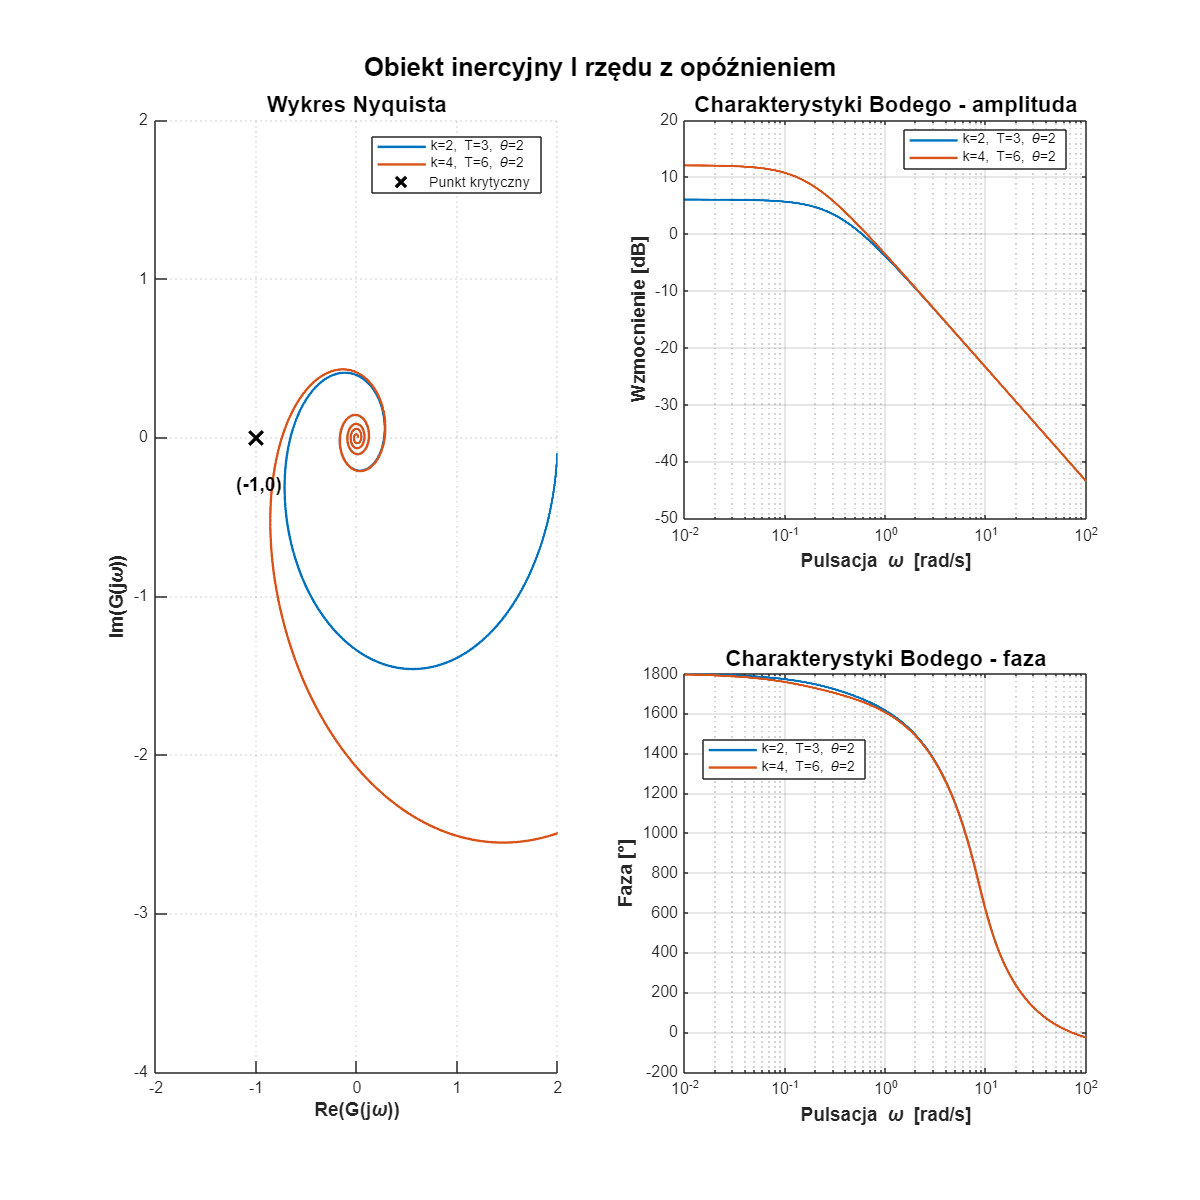

% Parametry układów
n = 10;
theta = 2;
k = [2, 4]; 
T = [3, 6];

% Aproksymacja opóźnienia za pomocą aproksymacji Padé
[licz_op, mian_op] = pade(theta, n);

% Tworzenie transmitancji
sys = cell(1,2);
for i = 1:2
    licz_temp = [k(i)];
    mian_temp = [T(i), 1];
    [licz, mian] = series(licz_op, mian_op, licz_temp, mian_temp);
    sys{i} = tf(licz, mian);
end

% Zakres pulsacji
w = logspace(-2, 2, 2000);

% Obliczanie odpowiedzi częstotliwościowej
mag = cell(1,2);
phase = cell(1,2);
re = cell(1,2);
im = cell(1,2);

for i = 1:2
    [mag_temp, phase_temp, ~] = bode(sys{i}, w);
    mag{i} = squeeze(mag_temp);
    phase{i} = squeeze(phase_temp);
    
    [re_temp, im_temp, ~] = nyquist(sys{i}, w);
    re{i} = squeeze(re_temp);
    im{i} = squeeze(im_temp);
end

% Tworzenie okna wykresów
figure('Position', [100, 100, 1000, 1000]);
sgtitle('Obiekt inercyjny I rzędu z opóźnieniem', 'FontSize', 16, 'FontWeight', 'bold');

colors = lines(2);

%% Wykres Nyquista (lewa strona)
subplot(1,2,1);
hold on;
for i = 1:2
    plot(re{i}, im{i}, 'Color', colors(i,:), 'LineWidth', 1.5);
end
plot(-1, 0, 'kx', 'MarkerSize', 12, 'LineWidth', 2);
text(-1.2, -0.3, '(-1,0)', 'FontSize', 12, 'FontWeight', 'bold');
set(gca, 'GridLineStyle', ':');
hold off;
grid on;
axis([-2 2 -4 2]);
title('Wykres Nyquista', 'FontWeight', 'bold', 'FontSize', 14);
xlabel('Re(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Im(G(j\omega))', 'FontWeight', 'bold', 'FontSize', 12);
legend({sprintf('k=%d, T=%d, \\theta=%d', k(1), T(1), theta), ...
        sprintf('k=%d, T=%d, \\theta=%d', k(2), T(2), theta), ...
        'Punkt krytyczny'}, 'Location', 'best');

%% Wykresy Bodego (prawa strona)
% Amplituda
subplot(2,2,2);
semilogx(w, 20*log10(mag{1}), 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, 20*log10(mag{2}), 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Wzmocnienie [dB]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - amplituda', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('k=%d, T=%d, \\theta=%d', k(1), T(1), theta), ...
        sprintf('k=%d, T=%d, \\theta=%d', k(2), T(2), theta)}, 'Location', 'best');

% Faza
subplot(2,2,4);
semilogx(w, phase{1}, 'Color', colors(1,:), 'LineWidth', 1.5);
hold on;
semilogx(w, phase{2}, 'Color', colors(2,:), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Pulsacja \omega [rad/s]', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Faza [°]', 'FontWeight', 'bold', 'FontSize', 12);
title('Charakterystyki Bodego - faza', 'FontWeight', 'bold', 'FontSize', 14);
legend({sprintf('k=%d, T=%d, \\theta=%d', k(1), T(1), theta), ...
        sprintf('k=%d, T=%d, \\theta=%d', k(2), T(2), theta)}, 'Location', 'best');

set(findall(gcf, '-property', 'FontName'), 'FontName', 'Arial');